## **Assignment-VI**

**Department of Applied Mathematics**

**Noakhali Science and Technology University**

**Course Code: A.MTH 4102, Course Title: Math Practical -V (Using MATLAB)**

*"Good Code is its own best Documentation"*

***-Steve McConnell***

**Question-1:**  Write a MATLAB program that will read a number n and will make a list of multiples of 3 or 5 up to n. Test it for n=50. 

**Answer:**

n=input('Enter number: ');

fprintf('Multiplies 3 and 5 up to %d are: \n',n);

Multiplies 3 and 5 up to 50 are: 


for i=1:n
 if((mod(i,3)==0) || (mod(i,5)==0))
 fprintf('%d ',i);
 else
 fprintf('');
 end
end

3 5 6 9 10 12 15 18 20 21 24 25 27 30 33 35 36 39 40 42 45 48 50 

**Question-2:** Differentiate the following: 

[a] ${\textrm{𝑒}}^{x^2 } \;\textrm{with}\;\textrm{respect}\;\textrm{to}\;{\textrm{𝑥}}^3$

[b] $2^{{\textrm{𝑡𝑎𝑛}}^{-1} \textrm{𝑥}} \;\textrm{with}\;\textrm{respect}\;\textrm{to}\log \left(1+{\textrm{𝑥}}^2 \right)$

**Answer:**

syms x 
res1 = x^3;
res2 = log(1+x^2);

f1 = exp(x^2);
f2 = 2^(atan(x));
disp(diff(f1/diff(res1),x));

$$\frac{2\,{\mathrm{e}}^{x^{2}}}{3\,x}-\frac{2\,{\mathrm{e}}^{x^{2}}}{3\,x^{3}}$$

disp(diff(f2/diff(res2),x));

$$2^{\mathrm{atan}\left(x\right)}-\frac{2^{\mathrm{atan}\left(x\right)}\,\left(x^{2}+1\right)}{2\,x^{2}}+\frac{2^{\mathrm{atan}\left(x\right)}\,\log\left(2\right)}{2\,x}$$

**Question-3:**  Let  

$A=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 5
\end{array}\right\rbrack \;\textrm{and}$ $B=\left\lbrack \begin{array}{cc}
5 & 0\\
2 & 1
\end{array}\right\rbrack \;\;$ , then perform the following:

(a ) Compute  $A+B,A-B\;\;\textrm{and}\;\;3A-2B$

(b) $\textrm{Show}\;\;\textrm{that}\;\;\textrm{AB}\not= \textrm{BA},{\textrm{AB}}^{-1} ={\textrm{𝐵}}^{-1} {\textrm{𝐴}}^{-1} \;\;\textrm{and}$$\left(\textrm{𝐴𝐵}{\left.\right)}^T ={\textrm{𝐵}}^T {\textrm{𝐴}}^T \right.$

**Answer:**

syms A B
A = [1 0;0 5];
B = [5 0;2 1];

disp(A+B)

     6     0
     2     6



disp(A-B)

    -4     0
    -2     4



disp(3*A - 2*B)

    -7     0
    -4    13




disp(A*B)

     5     0
    10     5



disp(B*A)

     5     0
     2     5




disp(inv(A*B))

    0.2000         0
   -0.4000    0.2000



disp(inv(A))

    1.0000         0
         0    0.2000



disp(inv(B))

    0.2000         0
   -0.4000    1.0000



disp(inv(B)*inv(A))

    0.2000         0
   -0.4000    0.2000




disp((A*B)')

     5    10
     0     5



disp(B')

     5     2
     0     1



disp(A')

     1     0
     0     5



disp(B' * A')

     5    10
     0     5



**Question-4:**  If $A=\left\lbrack \begin{array}{cc}
3 & 2\\
-1 & 0
\end{array}\right\rbrack \;$ , then prove that $A^2 -3A+2I=0$ , where  ***I*** and  0 are respectively the unit  matrix and null matrix (zero matrix) of same order as A . 

**Answer:**

A = [3 2;-1 0];
I = eye(2,2);
disp(A^2 - 3*A + 2*I)

     0     0
     0     0



**Question-5:**  Suppose $\left\lbrack \begin{array}{ccccc}
1 & 2 & 3 & 1 & -1\\
2 & 0 & -1 & -1 & 1\\
3 & 3 & 1 & 1 & 1
\end{array}\right\rbrack$and 

$B=\left\lbrack \begin{array}{ccc}
1 & 3 & 1\\
2 & 1 & 2\\
3 & 2 & 1\\
1 & 1 & 2\\
3 & 2 & 1
\end{array}\right\rbrack$ Find AB and BA. Also, verify that  $\left(\textrm{𝐴𝐵}{\left.\right)}^T ={\textrm{𝐵}}^T {\textrm{𝐴}}^T \right.$

**Answer:**

A = [1 2 3 1 -1;2 0 -1 -1 1;3 3 1 2 1];
B = [1 3 1;2 1 2;3 2 1;1 1 2;3 2 1]

B =      1     3     1
     2     1     2
     3     2     1
     1     1     2
     3     2     1


% disp(A*B);
% disp(B*A)
disp((A*B)')

    12     1    17
    10     5    18
     9     0    15



disp(B' * A')

    12     1    17
    10     5    18
     9     0    15



**Question-6:**  Write a MATLAB program that will detect whether the matrix is orthonormal, symmetric or  skew-symmetric.

**Answer:**


fprintf('Matrix A is: \n');

Matrix A is: 


A=[0 2 -1;-2 0 -4;1 4 0]

A =      0     2    -1
    -2     0    -4
     1     4     0


fprintf('Transpose matrix is: \n');

Transpose matrix is: 


AT=A'

AT =      0    -2     1
     2     0     4
    -1    -4     0


if A==AT
 fprintf('A is symmetric matrix \n');
end
 if -A==AT
 fprintf('A is skew-symmetric matrix \n');
 end

A is skew-symmetric matrix 


 if A*AT==eye(3)
 fprintf('A is orthonormal matrix \n');
 end


**Question-7:**  SWrite a MATLAB code that will solve square system of linear equation using Cramer’s rule. 

**Answer:**

A = input("enter square coef matrix");
B = input("enter augmented matrix");
x = [];
if det(A) == 0
    fprintf("matrix is invalid")
else
    for i = 1:size(A,1)
        C = A;
        C(:,i)= B;
        x(i) = det(C)/det(A);
    end
    disp(x')
end

    5.2500
   -1.3333
    2.4000



**Question-8:**  Verify Cayley-Hamilton theorem for the following matrices: 


$$\left\lbrack a\right\rbrack \;A=\;\;\left\lbrack \begin{array}{ccc}
1 & 2 & 1\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$



$$\left\lbrack b\right\rbrack \;B=\;\;\left\lbrack \begin{array}{ccc}
1 & 2 & 2\\
3 & 1 & 0\\
1 & 1 & 1
\end{array}\right\rbrack$$


**Answer:**

**Cayley-Hamilton Theorem****.** *A matrix satisfies its own characteristic equation. That is, if the characteristic equation of an n* × *n matrix* **A** *is*


$$\begin{array}{l}
\lambda {\;}^n +a_{n-1} \lambda {\;}^{n-1} +\ldotp \ldotp \ldotp \ldotp \ldotp +a_1 \lambda +a_{0\;} =0\\
\textrm{then},\\
A^n +a_{n-1} A^{n-a} +\ldotp \ldotp \ldotp +a_1 A+a_0 I=0\ldotp \\
\textrm{where}\;I\;\textrm{is}\;\textrm{identity}\;\textrm{matrix}\;\textrm{of}\;\textrm{oder}\;\textrm{of}\;\textrm{matrix}\;A
\end{array}$$


syms l x t 
A = [1 2 1;0 1 0;0 0 1];
% p = expand(det(eye(size(A))*l - A));
disp(p)

$$l^{3}-3\,l^{2}+3\,l-1$$


polyA = charpoly(A);

eq = zeros(3);
disp(polyB);

$$x^{3}-3\,x^{2}+3\,x-1$$

for i=1:length(polyA)
    if i == length(polyA)
        eq = eq + polyA(i)*eye(3);
    else
        eq = eq + A^(length(polyA)-i) * polyA(i);
    end
end
disp(eq)

     0     0     0
     0     0     0
     0     0     0



**Question-9:**  Solve the following ordinary differential equations using MATLAB code:


$$\left\lbrack a\right\rbrack \;\frac{\textrm{𝑑𝑦}}{\textrm{𝑑𝑥}}=-\textrm{𝑎x}$$
      
$$\begin{array}{l}
\left\lbrack b\right\rbrack \;\;\frac{\textrm{df}}{\textrm{dx}}=f+\sin \left(t\right)\;\;\;\;\;\;\;\;\;\;\;\left\lbrack c\right\rbrack \;\;\;\;\frac{\textrm{dy}}{\textrm{dx}\;}=-\textrm{ax}\;,y\left(0\right)=b\;\;\;\;\;\;\\
\left\lbrack d\right\rbrack \;\;\frac{d^2 y}{{\textrm{dx}}^2 }=-y\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left\lbrack e\right\rbrack \;\frac{d^2 y}{{\textrm{dx}}^2 }=-a^2 y,y\left(0\right)=0,y^{\prime } \left(\frac{\pi }{a}\right)=0\\
\left\lbrack f\right\rbrack \;\frac{d^2 y}{{\textrm{dx}}^2 }=-\frac{\textrm{dy}}{\textrm{dx}}-y\;\\
\textrm{obtain}\;\textrm{this}\;\textrm{result}\;\textrm{in}\;\textrm{pretty}\;\textrm{form}
\end{array}$$


**Answer:**

% syms y(t)
% ode = diff(y,t) == t*y
% ySol(t) = dsolve(ode)
% cond = y(0) == 2;
% ySol(t) = dsolve(ode,cond)

%================solution (a)===================%
syms y(x) a
ode = diff(y,x)==-a*x;
sol = dsolve(ode);
disp(sol)

$$C_{1}-\frac{a\,x^{2}}{2}$$

%================solution (b)===================%
syms f(x) t
ode2 = diff(f,x) == f + sin(t);
disp(ode2)

$$\frac{\partial }{\partial x}f\left(x\right)=f\left(x\right)+\sin\left(t\right)$$

sol2 = dsolve(ode2);
disp(sol2)

$$C_{1}\,{\mathrm{e}}^{x}-\sin\left(t\right)$$

%================solution (c)===================%
syms b
ode3 = diff(y,x) == -a*x;
cond = y(0) == b;
sol3 = dsolve(ode3,cond);
disp(sol3)

$$b-\frac{a\,x^{2}}{2}$$

%================solution (d)===================%
ode4 = diff(y,x,2) == -y;
sol4 = dsolve(ode4);
disp(sol4)

$$C_{1}\,\cos\left(x\right)-C_{2}\,\sin\left(x\right)$$

%================solution (e)===================%
cond4 = y(0) == 0;
ode4 = diff(y,x,2) == -y;
sol4 = dsolve(ode4);
disp(sol4)

$$C_{1}\,\cos\left(x\right)-C_{2}\,\sin\left(x\right)$$

%================solution (f)===================%
Dy = diff(y);
ode5 = diff(y,x,2)==-a*y;
cond51 = y(0) == 1;
cond52 = Dy(0) == 0;
conds5 = [cond51 cond52];
sol5 = dsolve(ode5,conds5);
disp(sol5)

$$\frac{{\mathrm{e}}^{-\sqrt{-a}\,x}\,\left({\mathrm{e}}^{2\,\sqrt{-a}\,x}+1\right)}{2}$$

%================solution (g)===================%
Dy = diff(y);
ode6 = diff(y,x,2)==-Dy - y;
sol6 = dsolve(ode6);
disp(sol6)

$$C_{1}\,{\mathrm{e}}^{-\frac{x}{2}}\,\cos\left(\frac{\sqrt{3}\,x}{2}\right)-C_{2}\,{\mathrm{e}}^{-\frac{x}{2}}\,\sin\left(\frac{\sqrt{3}\,x}{2}\right)$$



%for better documentation
% syms y(x)
% Dy = diff(y);
% 
% ode = diff(y,x,2) == cos(2*x)-y;
% cond1 = y(0) == 1;
% cond2 = Dy(0) == 0;
% 
% conds = [cond1 cond2];
% ySol(x) = dsolve(ode,conds);
% ySol = simplify(ySol)

**Question-10:**  Write a MATLAB code to solve the system of linear ordinary differential equations:

  
$$\begin{array}{l}
\frac{\textrm{dx}}{\textrm{dt}}=y\\
\frac{\textrm{dy}}{\textrm{dt}}=-x
\end{array}$$


**Answer:**

% syms u(t) v(t)
% ode1 = diff(u) == 3*u + 4*v;
% ode2 = diff(v) == -4*u + 3*v;
% odes = [ode1; ode2]
%S = dsolve(odes)

syms y(t) x(t)
ode1 = diff(x,t) == y;
ode2 = diff(y,t) == -x;
odes = [ode1; ode2];
sol = dsolve(odes);
disp(sol)

    y: C2*cos(t) - C1*sin(t)
    x: C1*cos(t) + C2*sin(t)



**Question-10:**  Write a MATLAB program that will read n nonzero values and then will calculate their  geometric mean and harmonic mean. Test it for n=3 and values 1,2 and 3.

**Answer:**

A = input("insert non-zero values")

A = 3

gm = geomean(A);
hm = harmmean(A);
disp(gm)

    3.0000



disp(hm)

     3



**Question-11:** Write a MATLAB program that will read n nonzero values and then will calculate their four  central moments, skewness and kurtosis.

**Answer:**

p = input("Enter non-zero values");
disp(moment(p,2))

    0.6667



disp(skewness(p))

     0



disp(kurtosis(p))

    1.5000



**Question-12:**  Write a MATLAB program that will be useful to solve problems related to binomial  distribution and Poisson distribution. 

**Answer:**


$${\displaystyle f(k,n,p)=\Pr(k;n,p)=\Pr(X=k)={ {n}{k}}p^{k}(1-p)^{n-k}}$$


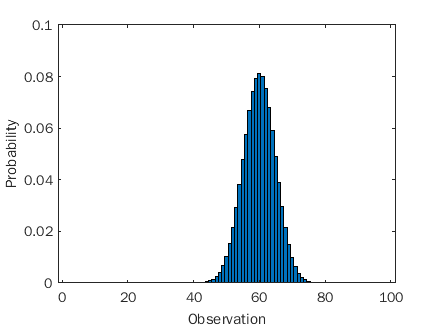


%========data input========%
N = 100;
p = 0.6;
bi_x = 0:N;
%===========data generate=====%
%=====pdf=probability density function========%
bipdf_y = binopdf(bi_x,N,p);
%===========figure for data distribution===========%
figure
bar(bi_x,bipdf_y,1)
xlabel('Observation')
ylabel('Probability')

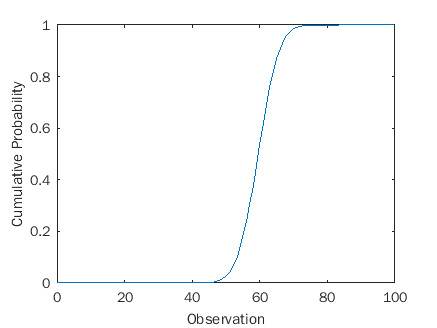

%==============================================

%==========figure for cumulative distribution of data===========%
%==============cdf = cumulative distribution function==============%
bicdf_y = binocdf(bi_x,N,p);
figure
% stairs(bi_x,bicdf_y)
plot(bi_x,bicdf_y)
xlabel('Observation')
ylabel('Cumulative Probability')

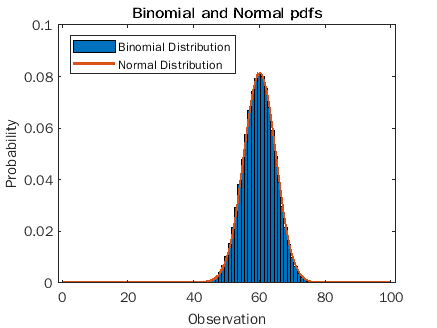

%===================================================%


%============= fitting with normal distribution=======%
%================data generation=================%
mu1 = N*p;
sigma = sqrt(N*p*(1-p));
nor_x = 0:0.1:N;
norpdf_y = normpdf(nor_x,mu1,sigma);

%============figure generation===========%
figure
bar(bi_x,bipdf_y,1)
hold on
plot(nor_x,norpdf_y,'LineWidth',2)
xlabel('Observation')
ylabel('Probability')
title('Binomial and Normal pdfs')
legend('Binomial Distribution','Normal Distribution','location','northwest')
hold off

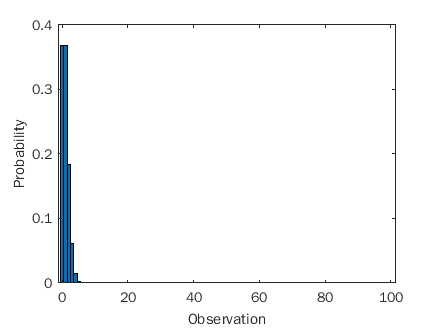


%======================possion distribution====================%

%====================poission probability distribution
%function================%
lambda = 1;        %lambda is mean%
pos_x = 0:N;
pospdf_y = poisspdf(pos_x,lambda);


figure
bar(pos_x,pospdf_y,1)
xlabel('Observation')
ylabel('Probability')

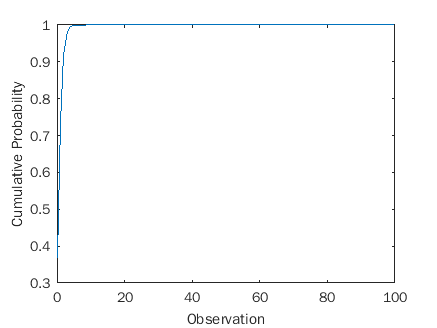

%================================================%

%================poission cumulative distribution function=============%
poscdf_y = poisscdf(pos_x,lambda);


figure
% stairs(pos_x,poscdf_y)
plot(pos_x,poscdf_y)
xlabel('Observation')
ylabel('Cumulative Probability')

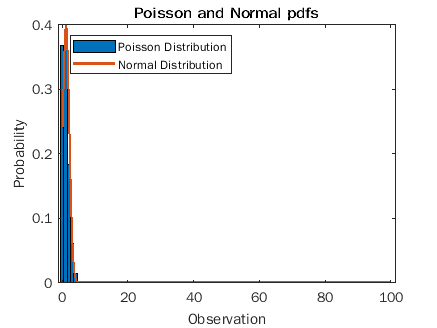

%================================%


%==============fit with normal distribution===============%
%==============normal distribution data generate=================%
mu2 = lambda;
sigma = sqrt(lambda);
nor_x2 = 0:0.1:N;
norpdf_y2 = normpdf(nor_x2,mu2,sigma);


figure
bar(pos_x,pospdf_y,1)
hold on
plot(nor_x2,norpdf_y2,'LineWidth',2)
xlabel('Observation')
ylabel('Probability')
title('Poisson and Normal pdfs')
legend('Poisson Distribution','Normal Distribution','location','northwest')
hold off

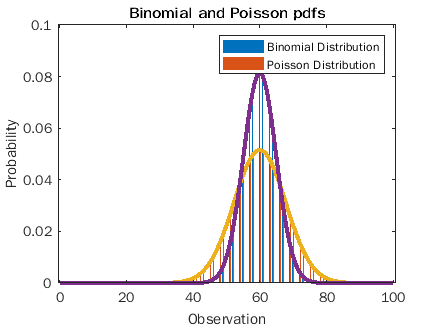

%=============================

%compare binomial and poission
mu2 = mu1;
sigma1 = sqrt(mu1);

norpdf_y2 = normpdf(nor_x2,mu2,sigma1);

pospdf_y1 = poisspdf(pos_x,mu1);
figure
bar(bi_x,[bipdf_y; pospdf_y1])
hold on
plot(nor_x2,norpdf_y2, 'LineWidth',3)
plot(nor_x2,norpdf_y, 'LineWidth',3)
xlabel('Observation')
ylabel('Probability')
title('Binomial and Poisson pdfs')
legend('Binomial Distribution','Poisson Distribution','location','northeast')

**Question-13:** Write a MATLAB program that will be useful to solve problems related to normal distribution

**Answer:**

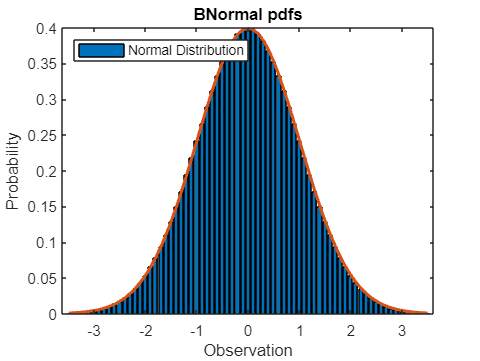

N = 100;
p = 0.5;
mu1 = 0;
sigma = 1;
nor_x = -3.5:0.1:3.5;
norpdf_y = normpdf(nor_x,mu1,sigma);

%============figure generation===========%
figure
bar(nor_x,norpdf_y)
hold on
plot(nor_x,norpdf_y,'LineWidth',2)
xlabel('Observation')
ylabel('Probability')
title('BNormal pdfs')
legend('Normal Distribution','location','northwest')
hold off

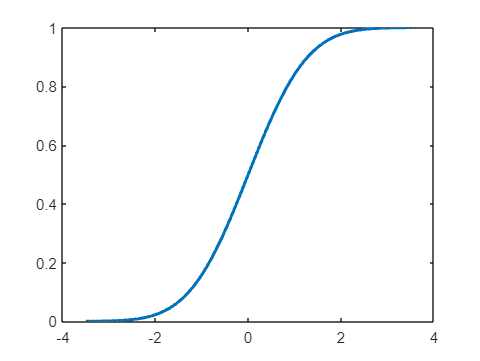

norcdf_y = normcdf(nor_x,mu1,sigma);
plot(nor_x,norcdf_y,'LineWidth',2)

**Question-14:**  Create a text file containing tabular probability values of z-score using a MATLAB program. 

**Answer:**

y_val = -3.5:0.1:3.5;
x_val = 0:0.01:0.099;
standardNormalTable = zeros(length(y_val),length(x_val));
for i=1:length(y_val)
    for j=1:length(x_val)

        z = round(y_val(i)+x_val(j),2);
        value = integral(@(x) 1.0/sqrt(2*pi) *exp((-x.^2)/2.0),-inf,z);
        standardNormalTable(i,j) = value;

    end

end


rowName = string(y_val);
colName = string(x_val');
T = array2table(standardNormalTable,...
    'VariableNames',colName,...
    'RowNames',rowName)

T = 71×10 table
                0            0.01          0.02          0.03          0.04          0.05          0.06          0.07          0.08          0.09   
            __________    __________    __________    __________    __________    __________    __________    __________    __________    __________

    -3.5    0.00023263    0.00024151    0.00025071    0.00026023    0.00027009    0.00028029    0.00029086    0.00030179    0.00031311    0.00032481
    -3.4    0.00033693    0.00034946    0.00036243    0.00037584    0.00038971    0.00040406    0.00041889    0.00043423    0.00045009    0.00046648
    -

writetable(T,'11.txt','WriteRowNames',true)  
% type 'myPatientData.dat'


function y = normalProbabilityDensity(x)
    constant = 1.0/sqrt(2*pi);
    y = constant * exp((-x.^2)/2.0);
end